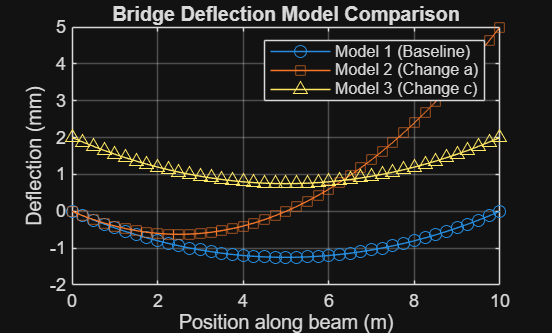

%{
ridge Deflection Model Comparison (Quadratic + Sensitivity)
Author: Diem-Linh Phan
Date: 4-30-2026
Purpose:
    Models a bridge beam when certain properties change
Input:
    - N/A:  Function is not expecting arguments.
Output:
    - Graph showing the location of deflection for each model
Engineering Algorithms:
    - Piecewise linear modeling
    - Numerical Vectorization 
    - Comparison Logic and Thresholding  
MATLAB tools/functions:
    - Vector Arithmetic
    - Array Initialization
    - Colon Operator
%}
% Define the x range from 0 to 10 with increments of 0.25
x = 0:0.25:10;

% Define coefficients [a, b, c] for each model
m1_coeffs = [0.05, -0.5, 0];
m2_coeffs = [0.1, -0.5, 0];
m3_coeffs = [0.05, -0.5, 2];

% Task 3: Evaluate models
d1 = polyval(m1_coeffs, x);
d2 = polyval(m2_coeffs, x);
d3 = polyval(m3_coeffs, x);

% Task 4: Plotting
figure;
plot(x, d1, '-o', x, d2, '-s', x, d3, '-^');
xlabel('Position along beam (m)');
ylabel('Deflection (mm)');
title('Bridge Deflection Model Comparison');
legend('Model 1 (Baseline)', 'Model 2 (Change a)', 'Model 3 (Change c)');
grid on;


% Task 5: Identify and report minimums
[min1, idx1] = min(d1);
[min2, idx2] = min(d2);
[min3, idx3] = min(d3);

fprintf('Model 1 Min: %.2f mm at x = %.2f m\n', min1, x(idx1));

Model 1 Min: -1.25 mm at x = 5.00 m


fprintf('Model 2 Min: %.2f mm at x = %.2f m\n', min2, x(idx2));

Model 2 Min: -0.62 mm at x = 2.50 m


fprintf('Model 3 Min: %.2f mm at x = %.2f m\n', min3, x(idx3));

Model 3 Min: 0.75 mm at x = 5.00 m


%{
changing a causes a larger curve on the graph, meaning it is less stiff.
changing c shows how the baseline will change.
%}
